# Problem 3

## 3.1 Design your stimulus

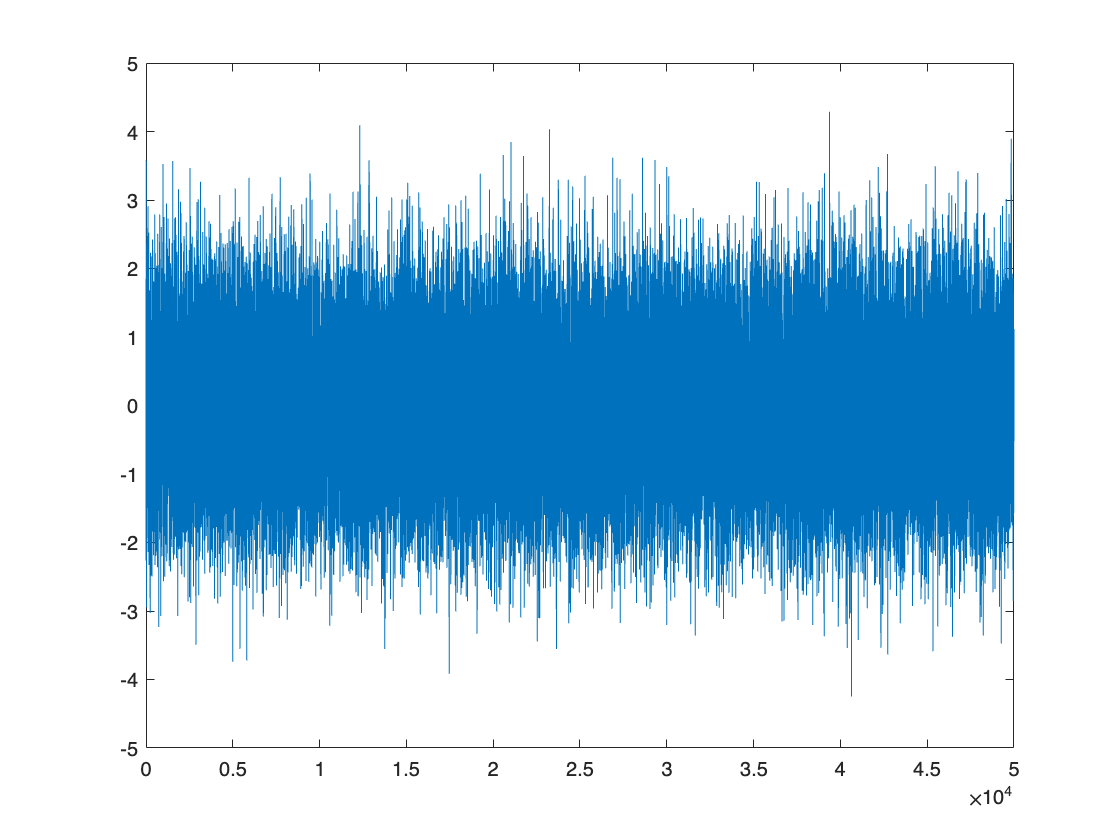

binWidth = 2e-3;
T = 1e2;
numBins = T / binWidth;

s = normrnd(0, 1, 1,numBins);
figure;
plot(s);

## 3.2 Simulate data

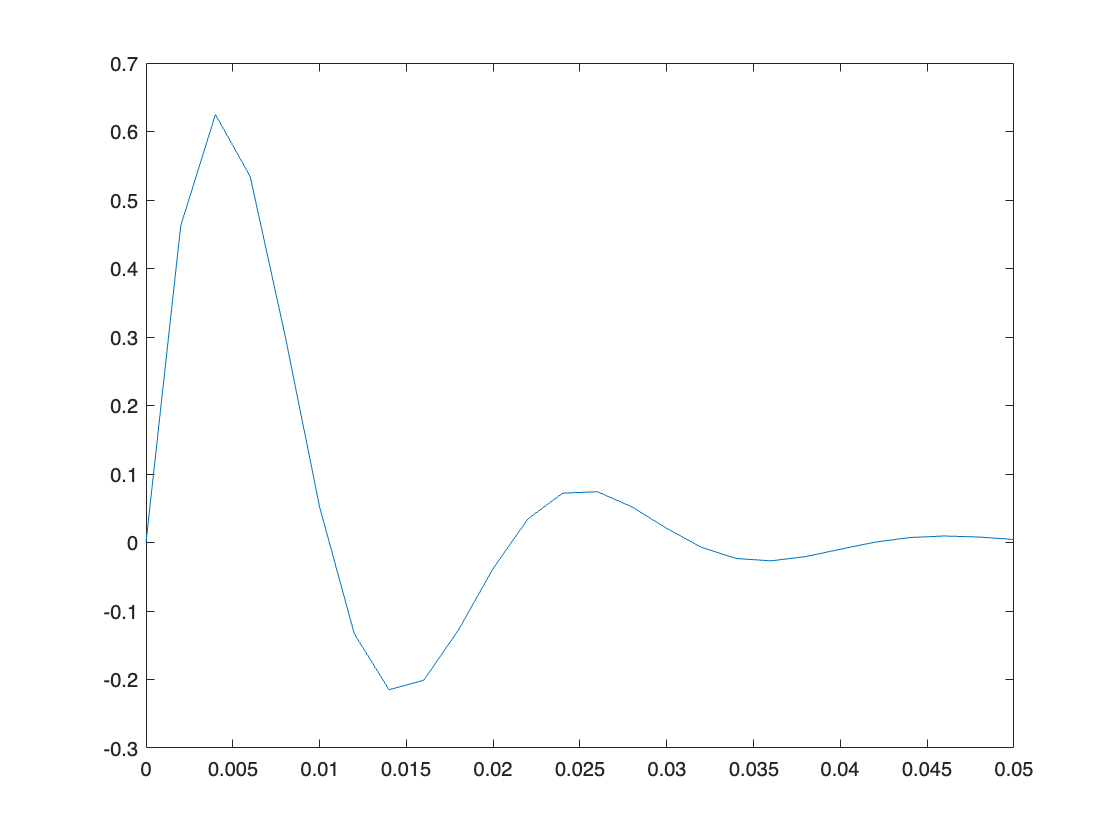

tau = 10e-3;
w = 0.3e3;

t = 0:binWidth:50e-3;
f = exp(-t ./ tau) .* sin(w * t);
figure;
plot(t,f)

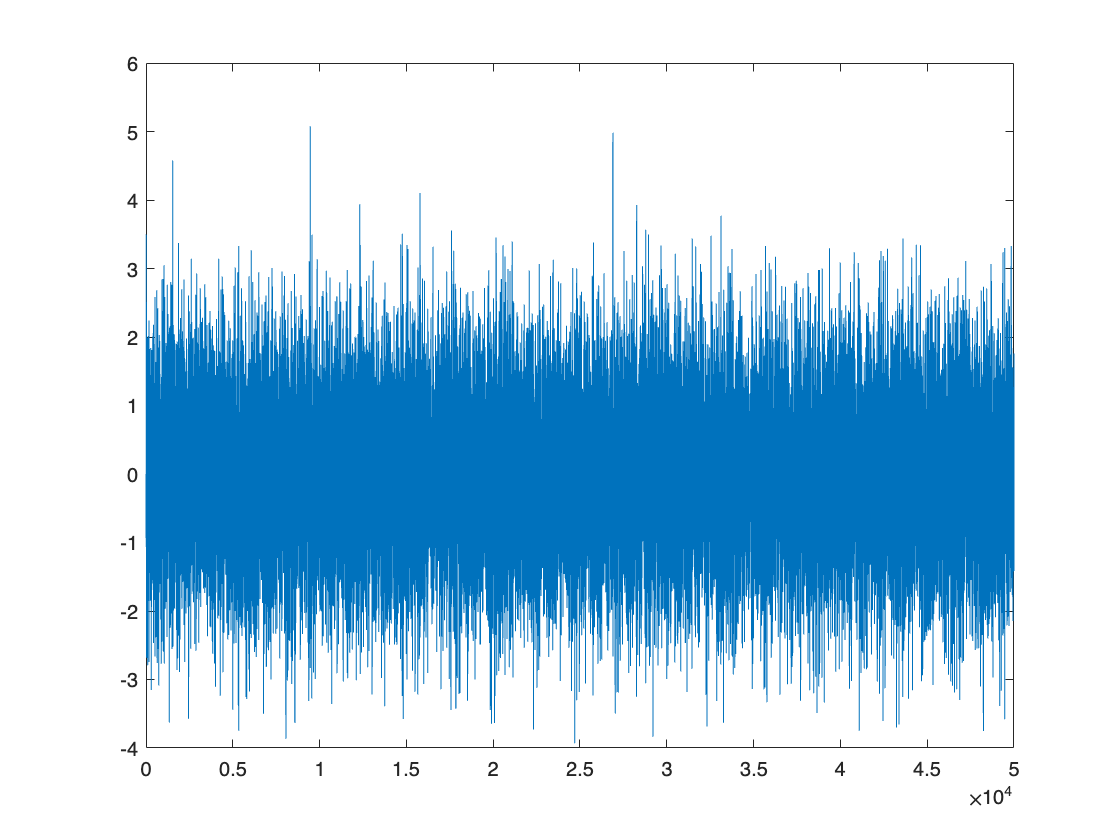

u = conv(s, f,"full");
u = u(1:length(s));
figure;
plot(u);

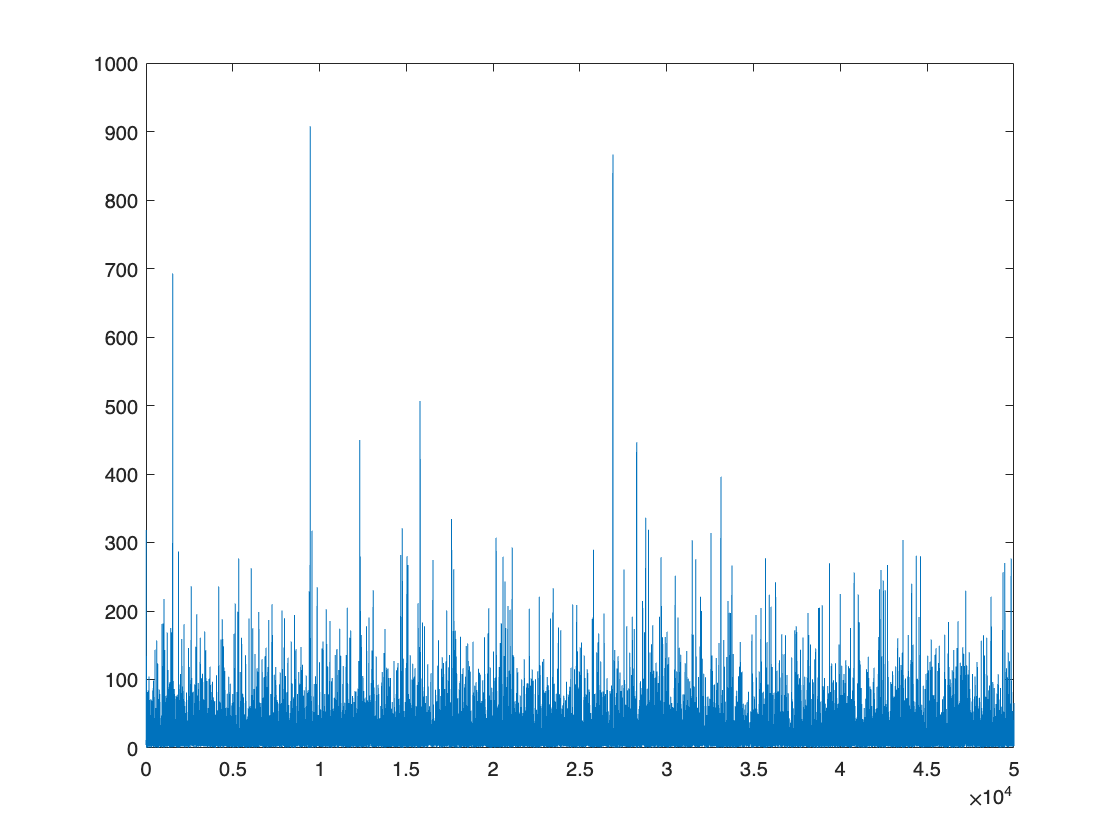

theta = 5;    
delta = 1;    
rMax = 1750; 

r = rMax ./ (1 + exp((theta - u)./delta));
figure;
plot(r);

% Generate a spike train
firingProb = r .* binWidth;
spikes = rand(size(r)) < firingProb;
%stem(spikes)
fr = sum(spikes) ./ T

fr = 19.2700

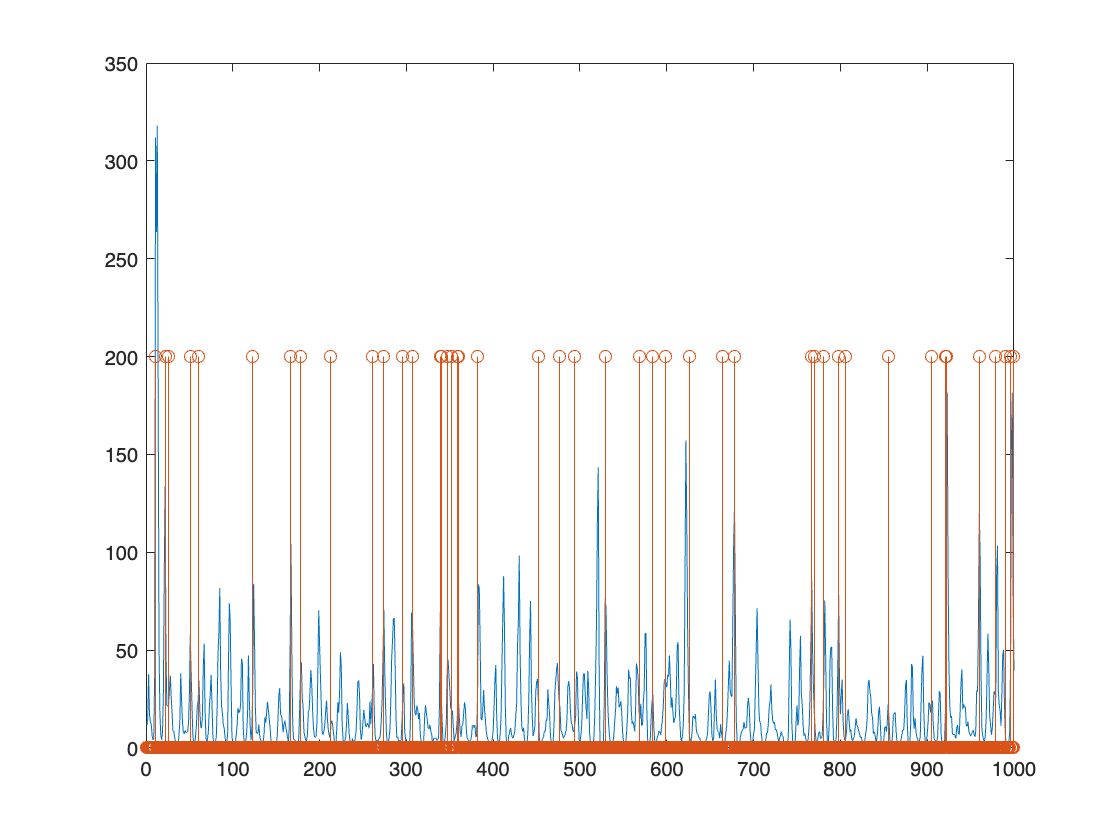

figure;
plot(r(1:1e3)); hold on; stem(200 * spikes(1:1e3));

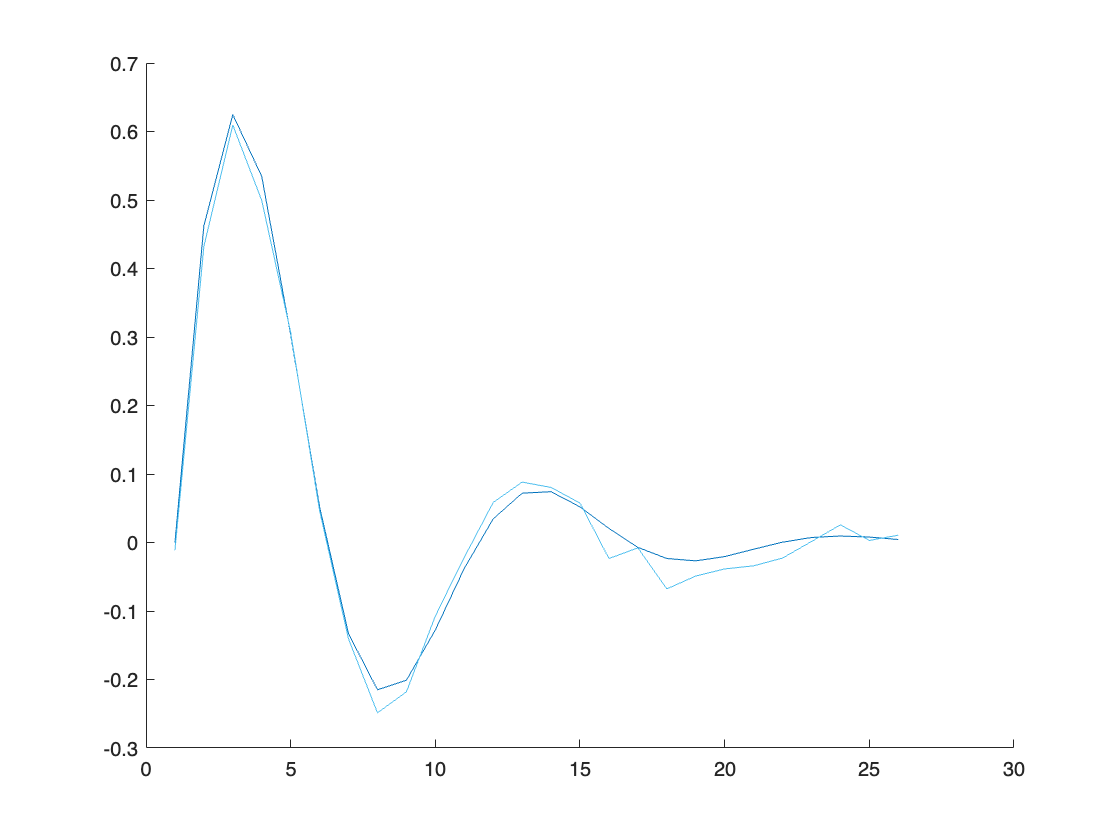

spikeTimes = find(spikes);
spikeTimes = spikeTimes(spikeTimes > length(f));
% for each spike
STA = zeros(size(f));

for i = 1:length(spikeTimes)
    windowEnd = spikeTimes(i);
    windowStart = windowEnd - length(f) + 1;
    assert(length(windowStart:windowEnd) == length(f));

    STA = STA + s(windowStart:windowEnd).';
end

STA = STA / numel(spikeTimes);

figure;
hold on;
plot(f)
plot(flipud(STA));

theta=15;
delta=2;
r2 = rMax ./ (1 + exp((theta - u.^2)/delta));

% Generate a spike train
firingProb = r2 .* binWidth;
spikes = rand(size(r2)) < firingProb;
%stem(spikes)
fr = sum(spikes) ./ T

fr = 3.9200

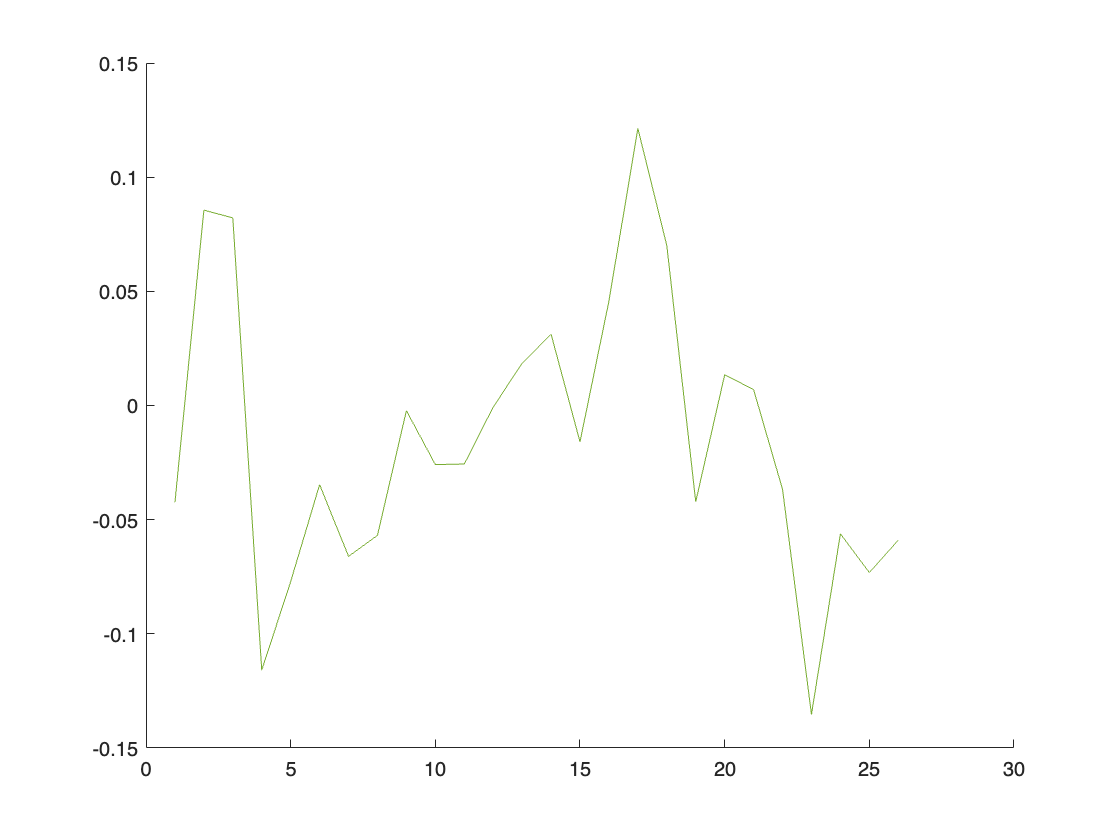


spikeTimes = find(spikes);
spikeTimes = spikeTimes(spikeTimes > length(f) & spikeTimes < length(r2));
% for each spike

STA = zeros(size(f));

for i = 1:length(spikeTimes)
    windowEnd = spikeTimes(i);
    windowStart = windowEnd - length(f) + 1;
    assert(length(windowStart:windowEnd) == length(f));

    STA = STA + s(windowStart:windowEnd).';
end

STA = STA / numel(spikeTimes);

figure;
hold on;
%plot(f)
plot(fliplr(STA));

STSegments = zeros(numel(spikeTimes), length(f));
%ControlSegments = zeros(numel(spikeTimes), length(f));

for i = 1:size(STSegments,1)
    windowEnd = spikeTimes(i);
    windowStart = windowEnd - length(f) + 1;
    assert(length(windowStart:windowEnd) == length(f));

    STSegments(i,:) = s(windowStart:windowEnd).';
end


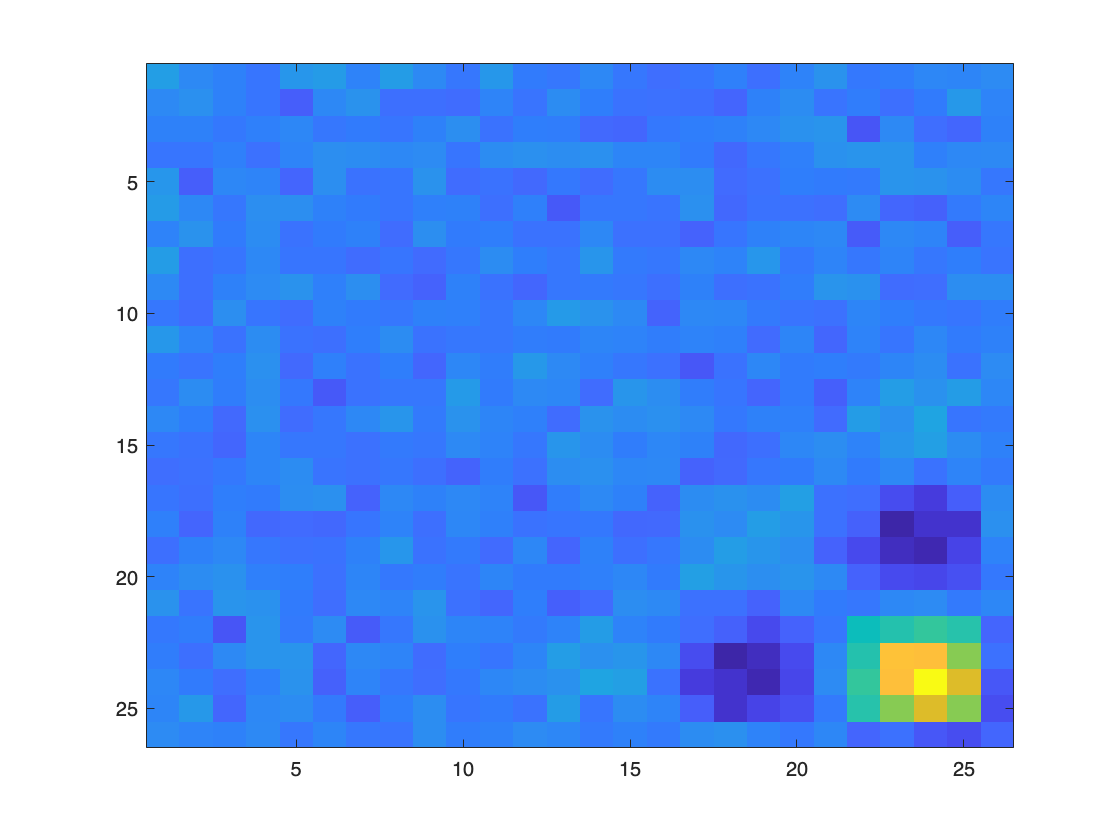

STA = mean(STSegments, 1);
STC = (STSegments - STA).' * (STSegments - STA) ./ ...
    (numel(spikeTimes)-1);

% Stimulus covariance
ControlSegments = zeros(numel(spikeTimes), length(f));

randomTimes = randsample(length(s)-length(f),numel(spikeTimes)) + length(f);
for i = 1:size(ControlSegments,1)
    windowEnd = randomTimes(i);
    windowStart = windowEnd - length(f) + 1;
    assert(length(windowStart:windowEnd) == length(f));
    ControlSegments(i,:) = s(windowStart:windowEnd).';
end

C = ControlSegments.' * ControlSegments ./ (numel(spikeTimes)-1);

figure;
imagesc(STC - C)

## 3.5 STC: Two-Dimensional Case

theta_f = 15;
theta_g = 15;
delta_f = 2;
delta_g = 2;
tau_f = tau;
tau_g = 30e-3;
w_f = w;
w_g = 0.2e3;
tt=0:2e-3:50e-3;
%rMax = 10000;

f = @(t) exp(-t ./ tau_f) .* sin(w_f * t);
g = @(t) -exp(-t ./ tau_g) .* cos(w_g * t);

r = @(uf,ug) rMax ./ ...
    (1+exp((theta_f-uf.^2)./delta_f)) ./ ...
    (1+exp((theta_g-ug.^2)./delta_g));

### **3.5.1**

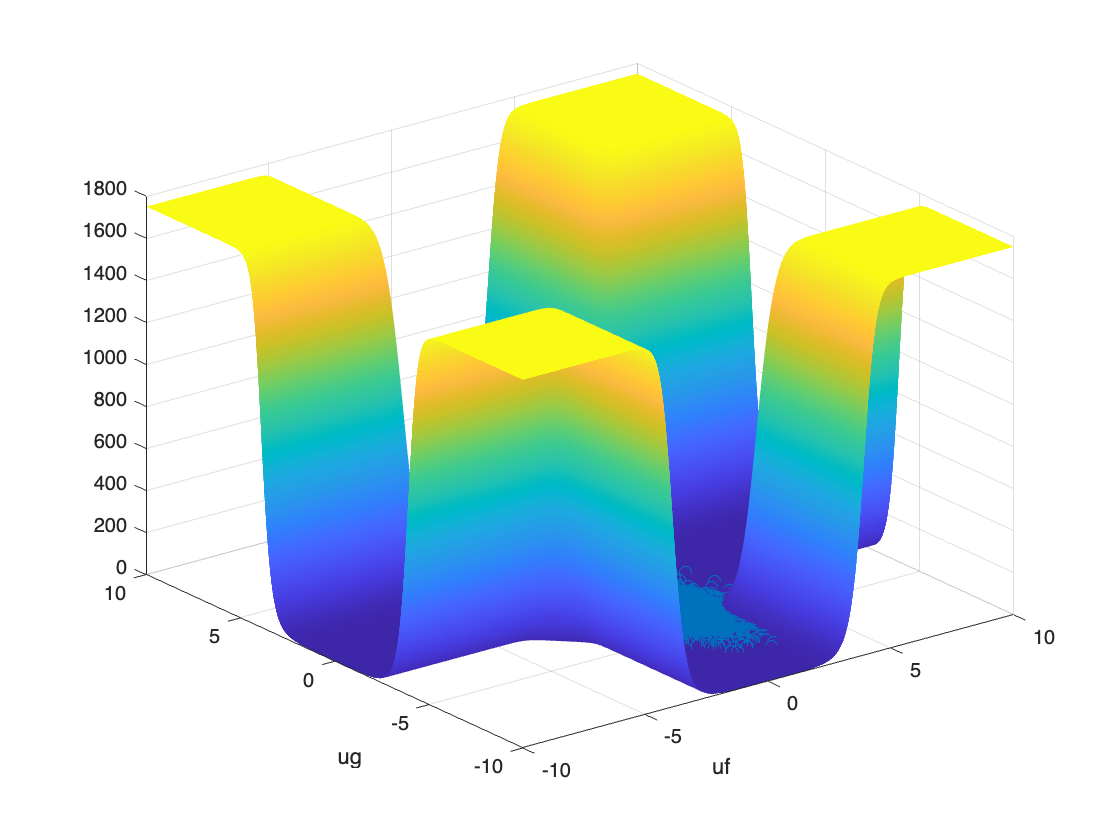

[uf,ug] = meshgrid(linspace(-10,10,1000),...
    linspace(-10,10,1000));
rTest = r(uf,ug);

uf2 = conv(s, f(tt),"full");
uf2 = uf2(1:length(s));
ug2 = conv(s, g(tt), "full");
ug2 = ug2(1:length(s));

figure;
surf(linspace(-10,10,1000), linspace(-10,10,1000), rTest, 'EdgeColor', 'none','FaceColor','interp');
xlabel('uf');
ylabel('ug');
hold on;
scatter(uf2, ug2);

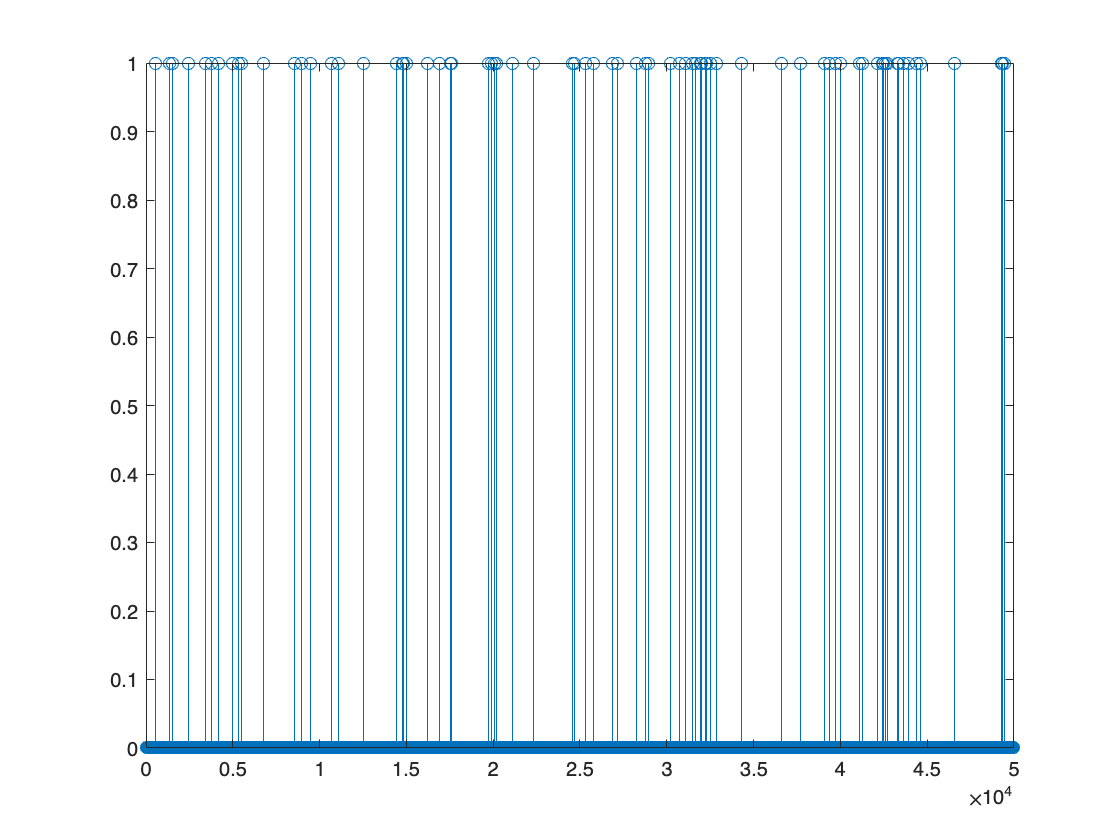

uf = conv(s, f(tt),"full");
uf = uf(1:length(s));

ug = conv(s, g(tt), "full");
ug = ug(1:length(s));

r_new = r(uf,ug);
spikes = r_new*binWidth > rand(size(r_new));

figure;
stem(spikes);

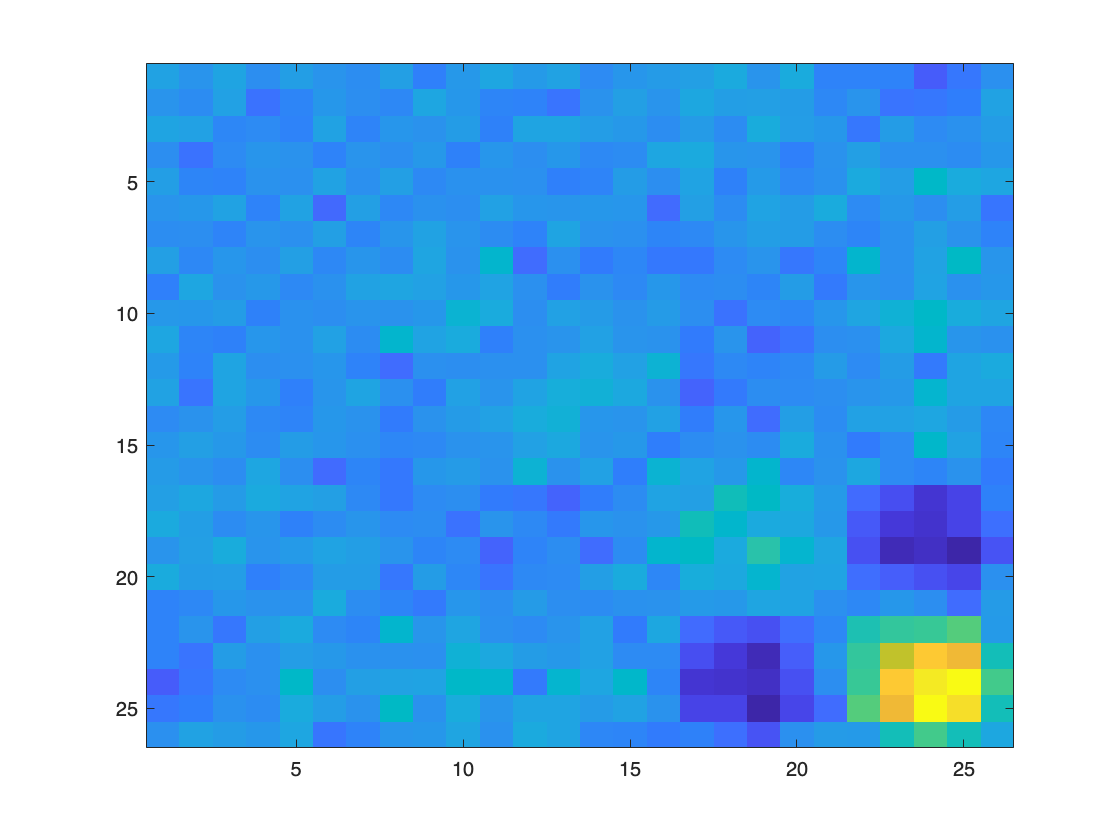

spikeTimes = find(spikes);
spikeTimes = spikeTimes(spikeTimes > length(tt));

STSegments = zeros(numel(spikeTimes), length(tt));
ControlSegments = zeros(numel(spikeTimes), length(tt));

for i = 1:size(STSegments,1)
    windowEnd = spikeTimes(i);
    windowStart = windowEnd - length(tt) + 1;
    assert(length(windowStart:windowEnd) == length(tt));

    STSegments(i,:) = s(windowStart:windowEnd).';
end

STA = mean(STSegments, 1);
STC = (STSegments - STA).' * (STSegments - STA) ./ ...
    (numel(spikeTimes)-1);

randomTimes = randsample(length(s)-length(tt),numel(spikeTimes))+length(tt);
for i = 1:size(ControlSegments,1)
    windowEnd = randomTimes(i);
    windowStart = windowEnd - length(tt) + 1;
    assert(length(windowStart:windowEnd) == length(tt));
    ControlSegments(i,:) = s(windowStart:windowEnd).';
end

C = ControlSegments.' * ControlSegments ./ (numel(spikeTimes)-1);

figure;
imagesc(STC - C);

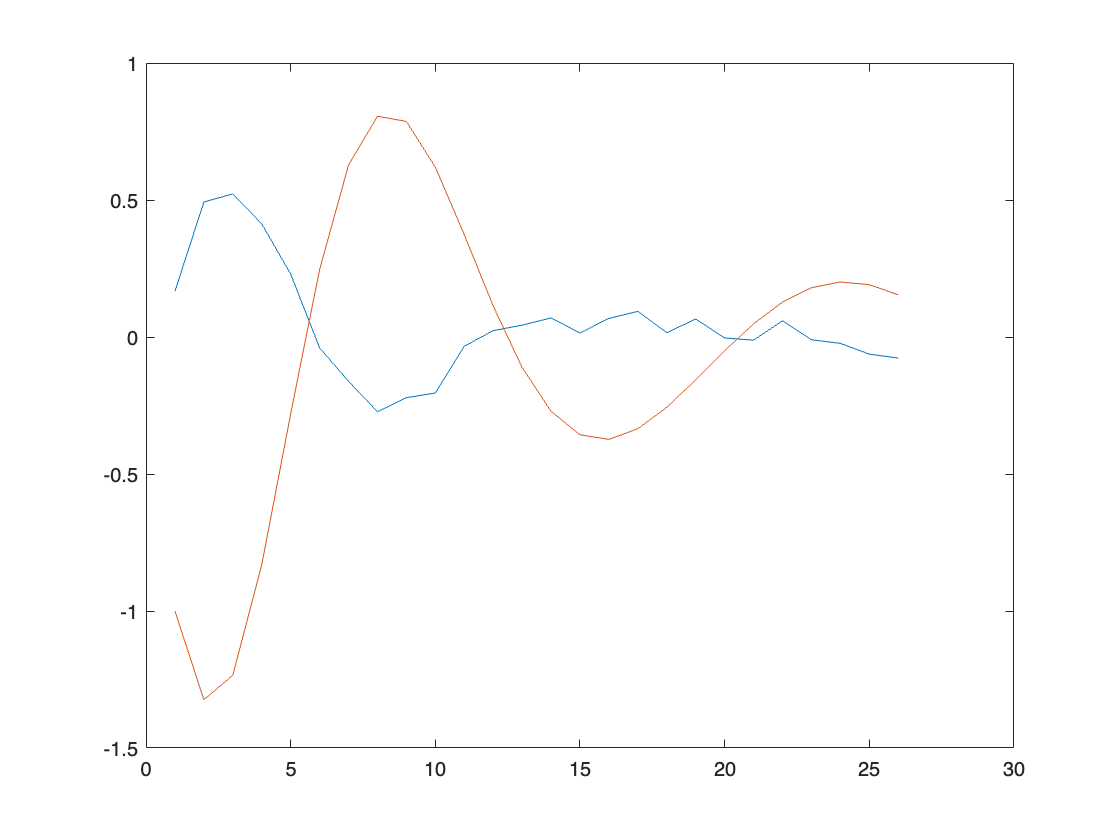

[V,D] = eig(STC - C);
figure;
plot(flipud(V(:,end)));
hold on
plot(-f(tt) + g(tt));

%plot(V(:,1));

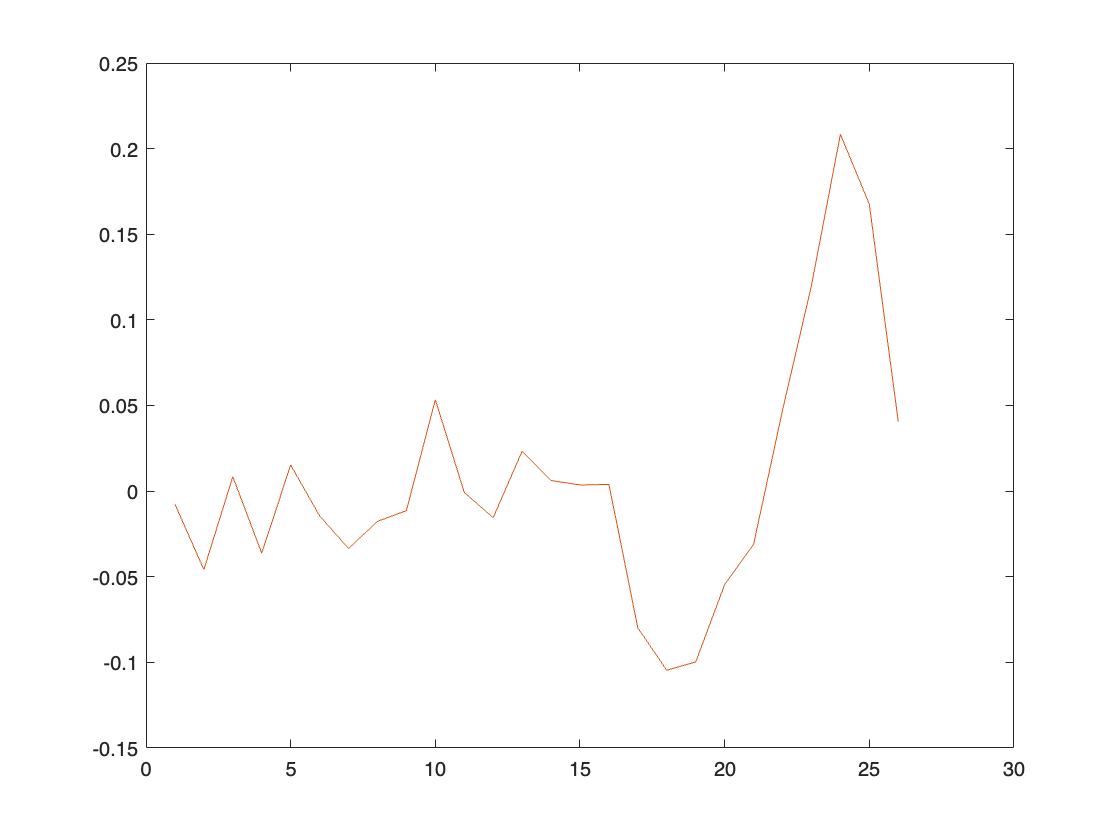

figure;
plot(mean(STC-C,1));
hold on;
plot(mean(STC-C,2));

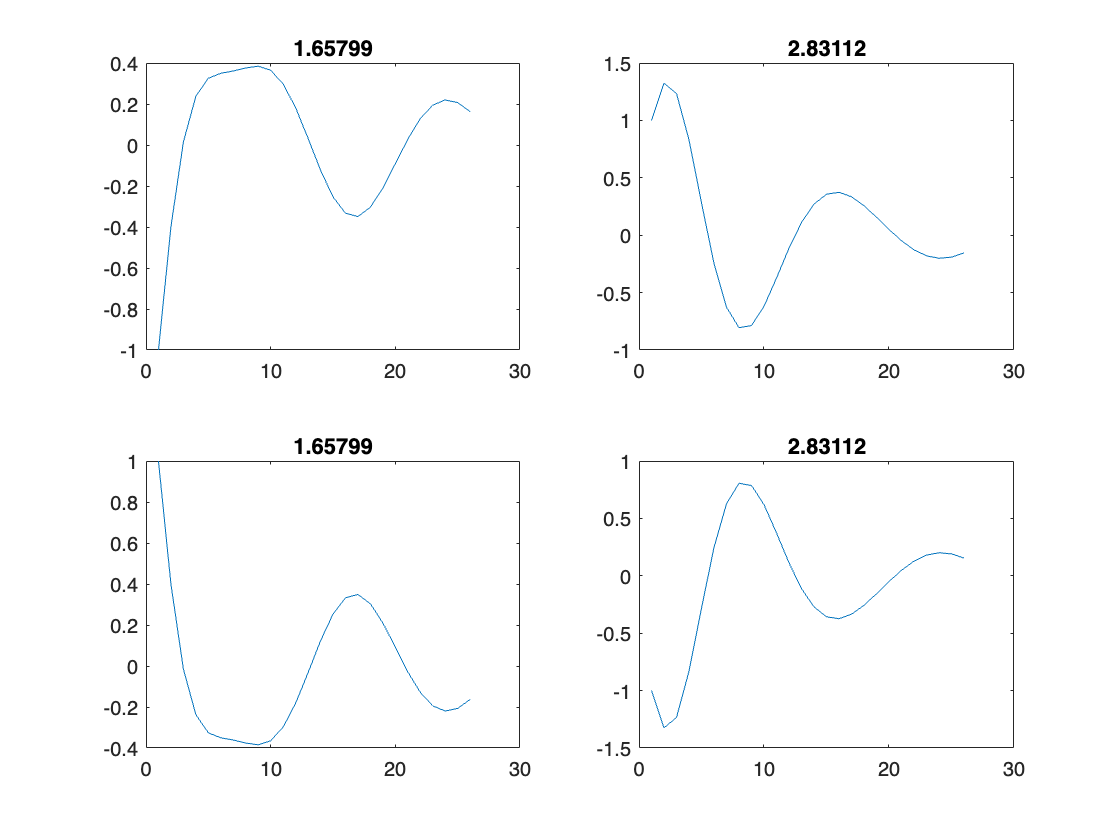

figure;
subplot(2,2,1);
plot(f(tt) + g(tt));
title(norm(f(tt) + g(tt)));
subplot(2,2,2);
plot(f(tt) - g(tt));
title(norm(f(tt) - g(tt)));
subplot(2,2,3);
plot(-f(tt) - g(tt));
title(norm(-f(tt) - g(tt)));
subplot(2,2,4);
plot(-f(tt) + g(tt));
title(norm(-f(tt) + g(tt)));

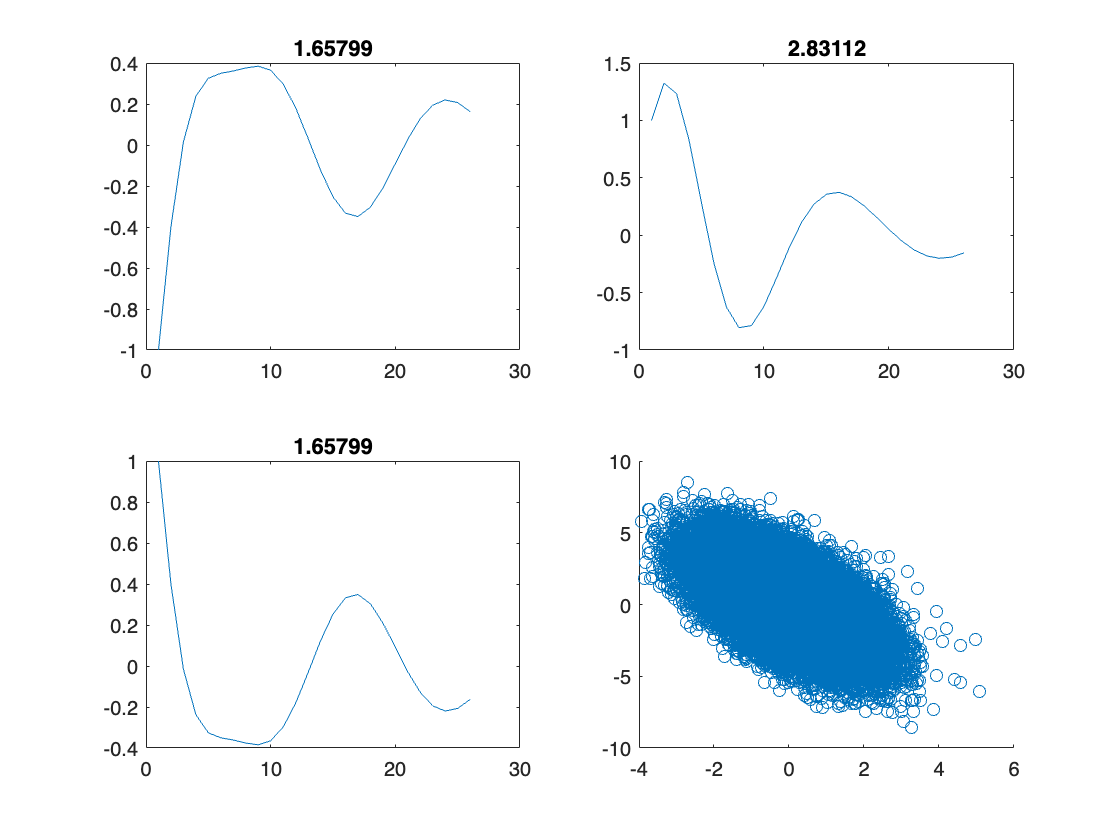

scatter(uf,ug);